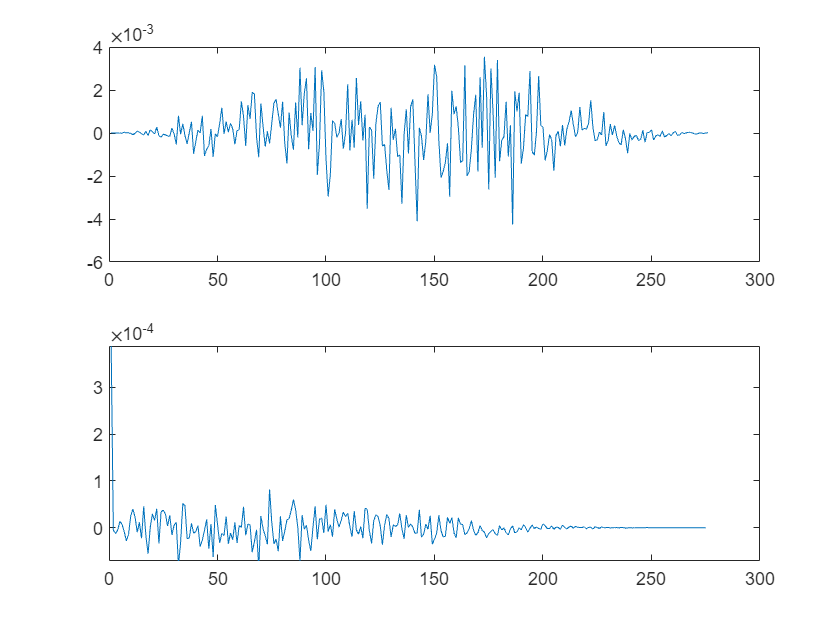

% Authors: 
% Lukas Bombel (lukas.bombel@uni-oldenburg.de)
% Jonte Kriebel (jonte.kriebel@uni-oldenburg.de)
% Philipp Kaiser (philipp.kaiser@uni-oldenburg.de)
% Robert Metzger (robert.metzger@uni-oldenburg.de)
% ------------------------------------------------------------------
clc
clear
close all

% read audio signal and resample
[vSentenceIn, iFs] = audioread('blaukraut.wav');
vSentenceIn = vSentenceIn(:,1);
%vSentenceIn = diff(vSentenceIn); % == Hochpassfilterung / Präemphase
vSentenceIn = resample(vSentenceIn,11025,iFs);
iFs = 11025;

% set parameters for blockwise processing
overlap = 0.5;
fBlockLength = 0.025;
fShift = fBlockLength*overlap;

% calculate block wise signal and put into matrix
[mOutput, iSamplesPerBlock, iSamplesPerShift, iNumBlocks, iSamplesMat] = output(vSentenceIn,iFs,fBlockLength,fShift);

% apply hann window on each signal block
mOutput_windowed = zeros(iSamplesPerBlock,iNumBlocks);
for i = 1:iNumBlocks
    mOutput_windowed(:,i) = hanning(size(mOutput,1)) .* mOutput(:,i);
end

% set filter order
iFilterOrder = 15;

% initiate error signal 
vEn = zeros(iSamplesMat,1);

% initiate noise vector
vNoise = randn(iSamplesMat,1)/100;

% initiate pulse train with wanted frequency
iPulseFreq = 300;
vPulse = zeros(iSamplesMat,1);
vPulse(1:round(iFs/iPulseFreq):end) = 0.05;

% preallocate signal vectors
vSentenceOut = zeros(iSamplesMat,1);
vSentenceOutNoise = zeros(iSamplesMat,1);
vSentenceOutPulse = zeros(iSamplesMat,1);

for i = 1:iNumBlocks
    % index for current block
    idx_start = (i-1)*iSamplesPerShift+1;
    idx_end = idx_start+iSamplesPerBlock-1;

    % calculate filter coefficients of block and save in matrix
    vLPC_coeff = lpc(mOutput_windowed(:,i), iFilterOrder);
    
    % obtain exitation signal from filtering original signal block
    mEn(:,i) = filter(vLPC_coeff,1,mOutput_windowed(:,i));
    
    vEn(idx_start:idx_end) = vEn(idx_start:idx_end) + filter(vLPC_coeff,1,mOutput_windowed(:,i));
    
    % synthesize all signals 
    vSentenceOut(idx_start:idx_end) = vSentenceOut(idx_start:idx_end) + filter(1,vLPC_coeff,mEn(:,i));
    vSentenceOutNoise(idx_start:idx_end) = vSentenceOutNoise(idx_start:idx_end) + ...
        hanning(iSamplesPerBlock) .* filter(1,vLPC_coeff,vNoise(idx_start:idx_end));
    vSentenceOutPulse(idx_start:idx_end) = vSentenceOutPulse(idx_start:idx_end) + ...
        hanning(iSamplesPerBlock) .* filter(1,vLPC_coeff,vPulse(idx_start:idx_end));
    % leistung pro fenster berechnen (hann gefenstert)
    % rms auf synth signal prägen
    % Nebenpuls 0.2 mal Leistung: ist wahrschenlich pulssignal
    % Rauschen: 0.15

    % write per block for spectrograms
    [mSentenceOut] = output(vSentenceOut, iFs, fBlockLength, fShift);
    [mSentenceOutNoise] = output(vSentenceOutNoise, iFs, fBlockLength, fShift);
    [mSentenceOutPulse] = output(vSentenceOutPulse, iFs, fBlockLength, fShift);
end

% calculate autocorrelation
for i = 1:iNumBlocks-1
    autocorrelation = xcorr(mEn(:,i));
    zero_idx = ceil(size(autocorrelation,1)/2);
    autocorrelation = autocorrelation(zero_idx:end);

    figure(999)
    title('Autocorrelation')
    subplot(2,1,1)
    plot(mEn(:,i))
    
    subplot(2,1,2)
    x_vec = 1:1:iSamplesPerBlock-1;
    scale_vec = linspace(1,1/iSamplesPerBlock,iSamplesPerBlock-1);
    plot(x_vec,autocorrelation(1:end-1)./scale_vec') % 
    ylim([min(autocorrelation) max(autocorrelation)])
    pause(0.01)
end


% figure()
% % freq_vec = 0:iSamplesPerBlock:iFs/(100*fBlockLength); % use linspace 
% vTime = linspace(0,length(vEn)/iFs,iNumBlocks-1);
% vFreq = linspace(0,iFs,iSamplesPerBlock+1000);
% waterfall(vTime,vFreq,autocorrelation(zero_idx:end,:))
% view(135,45)
% axis tight
% set(gca,'XDir','reverse')
% title('Autocorrelation of each block')
% xlabel('Time [s]')
% ylabel('Delay in samples')
% ylim([0 250])
% zlim([0 max(max(autocorrelation(round(end/2)+1:end,:)))])
% print('figures\waterfall_plot','-dpng')

% save the three signals as audio 
audiowrite('error.wav',vEn,iFs);
audiowrite('sigout.wav',vSentenceOut,iFs);
audiowrite('sigoutnoise.wav',vSentenceOutNoise,iFs);
audiowrite('sigoutpulse.wav',vSentenceOutPulse,iFs);

% use plot spectrogram function on the ouput signals
%plot_spectrogram(mSentenceOut, vTime, vFreq, 'original signal')
%plot_spectrogram(mSentenceOutPulse, vTime, vFreq, 'pulse signal')
%plot_spectrogram(mSentenceOutNoise, vTime, vFreq, 'noise signal')